function a = get_a(t,amax,t_ahold,t_vhold)
    t_vhold = 0;
    a = zeros(size(t));
    
    idx1 = (0 <= t) & (t < t_ahold);
    idx2 = ((t_ahold <= t) & (t < (t_ahold + t_vhold)));
    idx3 = (((t_ahold + t_vhold) <= t) & (t < (2*t_ahold + t_vhold)));
    
    a(idx1) = amax;
    a(idx2) = 0;
    a(idx3) = -amax;
end

function [a,v,s] = get_kin_functions(t,amax,t_ahold,delta_s)
    t_vhold = 0;
    dt = t(2) - t(1);
    
    a = get_a(t,amax,t_ahold,t_vhold) * sign(delta_s);
    v = cumsum(a) * dt;
    s = cumsum(v) * dt;
end

function t_ahold = get_t_ahold_without_t_vhold(delta_s,amax)
    t_ahold = sqrt(abs(delta_s) / amax);
end


close all; clear;

dt = 0.001;
t = [0];

ax = [0];
vx = [0];
sx = [0];

ay = [0];
vy = [0];
sy = [0];

amax = 1;

positions = [
    [0,             0]
    [-5,            .1]
    [0,            .2]
    ]

positions =          0         0
   -5.0000    0.1000
         0    0.2000



positions_size = size(positions);
num_of_positions = positions_size(1)

num_of_positions = 3


for i = [1:num_of_positions - 1]
    position = positions(i,:);
    next_position = positions(i + 1,:);

    delta_xy = next_position - position

    bigger_delta = delta_xy(1);
    smaller_delta = delta_xy(2);
    x_bigger = true;
    if abs(delta_xy(2)) > abs(delta_xy(1))
        bigger_delta = delta_xy(2);
        smaller_delta = delta_xy(1);
        x_bigger = false;
    end

    bigger_delta
    smaller_delta

    t_ahold = get_t_ahold_without_t_vhold(bigger_delta,amax)
    a_smaller = smaller_delta / t_ahold^2

    t_tot = 2 * t_ahold;

    t_temp = 0:dt:t_tot

    [a1,v1,s1] = get_kin_functions(t_temp,amax,t_ahold, bigger_delta);
    [a2,v2,s2] = get_kin_functions(t_temp,a_smaller,t_ahold, smaller_delta);

    t(end + 1: end + length(t_temp)) = t_temp + t(end);
    ax(end + 1: end + length(a1)) = a1;
    vx(end + 1: end + length(a1)) = v1;
    sx(end + 1: end + length(a1)) = s1 + sx(end);

end

delta_xy =    -5.0000    0.1000


bigger_delta = -5

smaller_delta = 0.1000

t_ahold = 2.2361

a_smaller = 0.0200

t_temp =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


delta_xy =     5.0000    0.1000


bigger_delta = 5

smaller_delta = 0.1000

t_ahold = 2.2361

a_smaller = 0.0200

t_temp =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490



t

t =          0         0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480


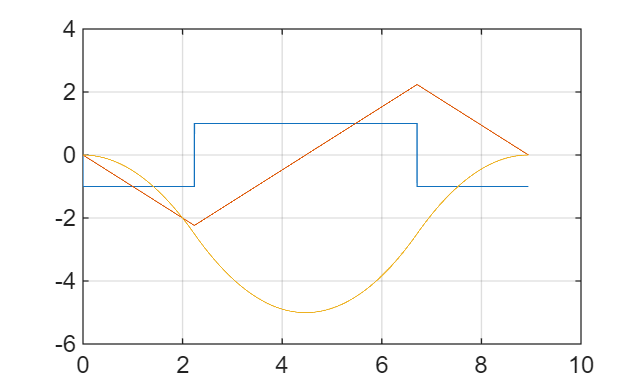

plot(t,ax,t,vx,t,sx);
hold on;
grid on;

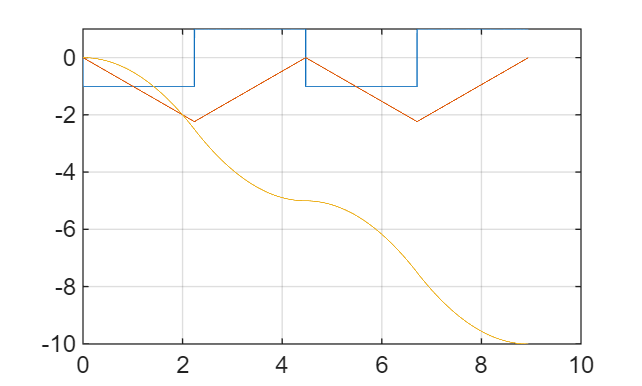

close all; clear;

dt = 0.001;
t = [0];

dim = 2;

a = zeros([dim 1]);
v = zeros([dim 1]);
s = zeros([dim 1]);

a_peak = zeros([1 dim]);

amax = 1;

positions = [
    [0,             0]
    [-5,            1]
    [-10,           0]
    ];

positions_size = size(positions);
num_of_positions = positions_size(1);

for i = [1:num_of_positions - 1]
    position = positions(i,:);
    next_position = positions(i + 1,:);

    delta_position = next_position - position;
    
    biggest_delta_i = 1;
    biggest_delta = 0;

    for j = [1:dim]
        if abs(delta_position(j)) >= abs(biggest_delta)
            biggest_delta_i = j;
            biggest_delta = delta_position(j);
        end
    end

    t_ahold = get_t_ahold_without_t_vhold(biggest_delta,amax);
    t_tot = 2 * t_ahold;

    a_peak(biggest_delta_i) = amax;

    for i = [1:dim]
        if i == biggest_delta_i
            continue
        end

        a_peak(i) = abs(delta_position(i)) / (t_ahold^2);
    end

    t_temp = 0:dt:t_tot;

    for i = [1:dim]

        [a_temp,v_temp,s_temp] = get_kin_functions(t_temp,a_peak(i),t_ahold, delta_position(i));

        a(i, length(t) + 1: length(t) + length(a_temp)) = a_temp;
        v(i, length(t) + 1: length(t) + length(v_temp)) = v_temp;
        s(i, length(t) + 1: length(t) + length(s_temp)) = s_temp + s(i, length(t));
    end

    t(end + 1: end + length(t_temp)) = t_temp + t(end);
end

plot(t,a(1,:),t,v(1,:),t,s(1,:));
grid on;

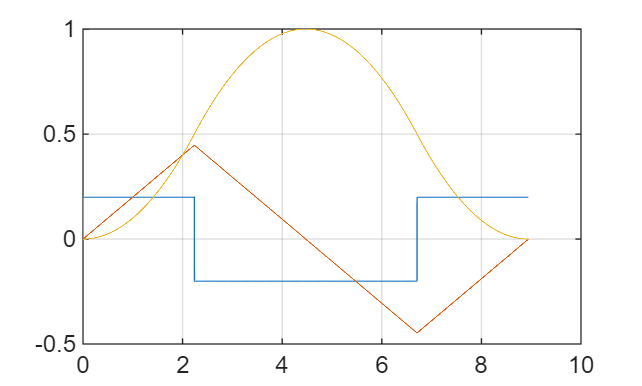

plot(t,a(2,:),t,v(2,:),t,s(2,:));
grid on;